**CmpE462 Assignment#1**

**Alptekin Orbay**

**2015400252**

Q1

The plot shows us order 3 has the minimum error value. This is meaningful as sinus seems to be a third order polynamial in the interval of (0,5). SInce, we know the real function and corresponding values, it becomes easy to compute the bias and variance, so the error.

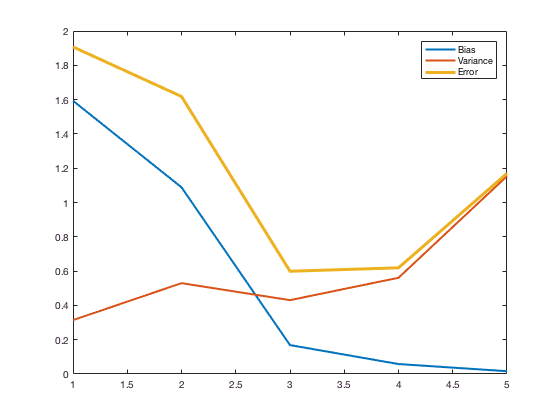

%% Case 1
clear all;
close all;
N = 20;
M = 100;
Degree = 5;
x = zeros(M,N);
for i=1:M
    x(i,:) = 5*sort(rand(1,N));
    %% Random x are generated.
    %% Sort is useful for debuging.
end

%% Initial Variables are declared.
Samples = zeros(M,N);
g_x = zeros(M,N);
mean_g_x = zeros(M,N);
Bias = zeros(1,Degree);
Variance = zeros(1,Degree);
f_x =  zeros(M,N);

%% Samples are generated 
for i = 1:M
    f_x(i,:) = 2 * sin(1.5 * x(i,:));
    noise = randn(1,N); % 
    Samples(i,:) = f_x(i,:) + noise;
end

%% Stantard X samples are generated.
x_sample = (0.4:20)/4;
for d = 1:Degree
    w  = zeros(M,d+1);
    for i = 1:M
        %% Fit calls for fitting Samples
        w(i,:) =fit(x(i,:),Samples(i,:),d);
    end
    for i=1:M
        %% g_x are genereated with standard.
        g_x(i,:) = poly(x_sample,w(i,:));
    end
    %% Mean of estimated functions are found.
    %% Real values are calculated based on standard X.
    %% Bias are calculated.
    mean_g_x  = sum(g_x)/M;
    fx = 2 * sin(1.5 * x_sample);
    Bias(d) =sum((mean_g_x - fx).^2)/N;
    %% Differences between
    %% each polynimals and
    %% mean polynimals.
    for i = 1:M
            Variance(d) = Variance(d) + sum((g_x(i,:) - mean_g_x ).^2);
    end
    Variance(d) = Variance(d)/(M*N);
end
Error = Bias + Variance;

plot([1:Degree],Bias,'LineWidth',2);
hold on;
plot([1:Degree],Variance,'LineWidth',2);
hold on;
plot([1:Degree],Error,'LineWidth',3);
legend('Bias','Variance','Error');

Q2

In this case, we do not know the real function and corresponding values. Hence, cross validation would be a nice option to select the best order of polynamial. We separate training and validation sets. We infer parameters from training and apply to the validation set. Eventually, the plot approves our assumptions. The graph become optimum at the same point with first case.

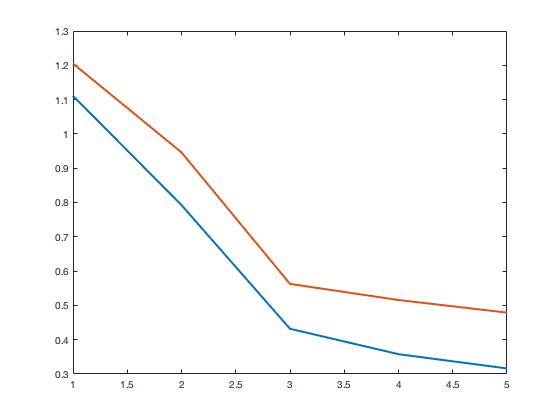

%% Case 2


%% Initial Variables
p = randperm(M);
t_size = 50*M/100;
v_size = M-t_size;
training_set = Samples(p(1:t_size),:);
training_set_x = x(p(1:t_size),:);
validation_set = Samples(p(t_size+1:M),:);
validation_set_x = x(p(t_size+1:M),:);
t_g_x = zeros(t_size,N);
t_error = zeros(1,Degree);
v_error = zeros(1,Degree);
g = zeros(t_size,N);

%% For each order
for d=1:Degree
    w  = zeros(t_size,d+1);
    %% Training set are used for poly coef.
    for i=1:t_size
        w(i,:)  = fit(training_set_x(i,:),training_set(i,:),d);
        gx = poly(training_set_x(i,:),w(i,:));
        t_error(d) = t_error(d) + sum((training_set(i,:) - gx).^2);
    end
    %% Estimated parameters are mean.
    mean_w = sum(w)/t_size;
        for j = 1:v_size
            %% Estimated parameters are tested on validation set
            %% and error accumulater.
            gx = poly(validation_set_x(j,:),mean_w);
            v_error(d) = v_error(d) + sum((validation_set(j,:) - gx).^2);
        end
   %% Error Means Are Calculated.
   t_error(d) = t_error(d) / (2 *t_size*N);
   v_error(d) = v_error(d) / (2 *v_size*N);
end
figure;
plot([1:Degree],t_error,'LineWidth',2);
hold on;
plot([1:Degree],v_error,'LineWidth',2);

Q3

Maxiumum likelihood estimation of gaussian distribution is simply variance and mean of the sample. Therefore, we can infer the parameters from selected training set. It is very suprising that  petal length is very good at classifying the flowers. Monte Carlo simulation is applied to find the success rate of the each feature  at the convergance.

mean values of setosa = [5.005,3.415,1.47,0.245]

std of setosa = [0.359,0.338,0.169,0.111]

mean values of versicolour = [5.94,2.77,4.24,1.33]

std of versicolour = [0.54,0.314,0.48,0.19]

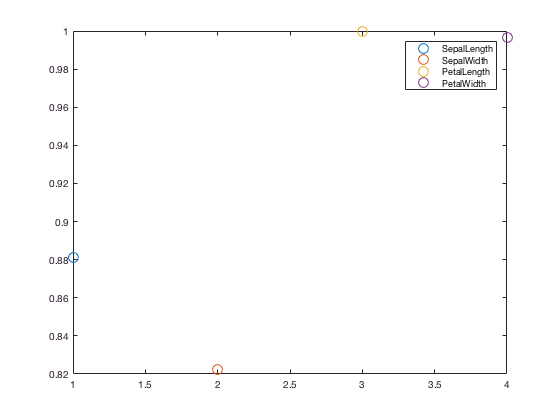

%%%%%%%%%%
%% Case 3
load('iris.mat');
setosa = iris.features(1:50,:);
versicolour = iris.features(51:100,:);
R = zeros(4,1);
Monte_Carlo = 200;
%% For most efficient feature 
%% Monte Carlo Simulation is applied.
for k = 1:Monte_Carlo
%% Traninng and Test Set is separated.
p = randperm(50);
K = 30;
L = 50 - K;
training = p(1:K);
test = p(K+1:50);
    %% For each feature parameter estimation is done.
    for i=1:4
        %%
        [u1,q1] = estimator(setosa(training,i)); 
        [u2,q2] = estimator(versicolour(training,i));
        t_set = [setosa(test,i)',versicolour(test,i)'];
        %% Relative Likelihood is calculated
        %% and compared to classidy.
        p_setosa = normpdf(t_set,u1,q1);
        p_versicolour = normpdf(t_set,u2,q2);
        %% Setosa is Labeled as 0.
        %% Versicolour is labeled as 1.
        results = p_setosa < p_versicolour;
        true =[zeros(1,L),ones(1,L)];
        compare = true - results;
        R(i) = R(i) + length(find(compare == 0)) /(2*L);
    end
end
R =  R / Monte_Carlo;
figure;
plot(1,R(1),'O','markersize',10);
hold on;
plot(2,R(2),'O','markersize',10);
hold on;
plot(3,R(3),'O','markersize',10);
hold on;
plot(4,R(4),'O','markersize',10);
hold on;
legend('SepalLength','SepalWidth','PetalLength','PetalWidth');

Appendix

function w = fit(x,y,degree)
observation_len = length(x);
D = zeros(observation_len,degree+1);
for i = 1:observation_len
    for j = 1:degree+1
        D(i,j) = x(i)^(j-1);
    end
end
    w = pinv(D'*D)*D'*y';
end


function y  = poly(x,w)
y = zeros(1,length(x));
degree = length(w);
for i = 1:degree
    y = y + x.^(i-1)*w(i);
end
end

function [u ,q] = estimator(x)
N = length(x);
u = sum(x)/N;
q = sqrt(sum((x - u).^2)/(N));
end